clear all; close all; clc;


## Verifica della function "CL.m"

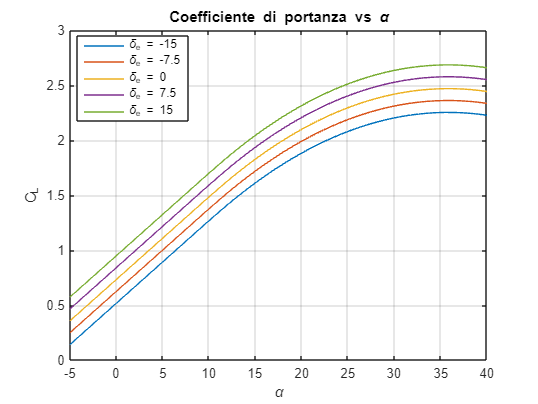

% è stato verificato che chiede tutto in gradi

v_alphaB_deg = linspace(-5,40,50);
v_delta_e_deg = linspace(-15,15,5);

m_CL = zeros(length(v_alphaB_deg), length(v_delta_e_deg));
for i_alpha = 1:length(v_alphaB_deg)
    alphaB = v_alphaB_deg(i_alpha);
    for i_delta_e = 1:length(v_delta_e_deg)
        delta_e = v_delta_e_deg(i_delta_e);
        m_CL(i_alpha, i_delta_e) = CL(alphaB, delta_e);
    end
end
figure(1)
for i_delta_e = 1:length(v_delta_e_deg)
    plot(v_alphaB_deg, m_CL(:,i_delta_e), 'DisplayName', ['\delta_e = ' num2str(v_delta_e_deg(i_delta_e))]);
    hold on

end
legend('show',"Position", [0.14768,0.70556,0.2,0.20476]);
xlabel('\alpha');
ylabel('C_L');
grid on;
title('Coefficiente di portanza vs \alpha')
hold off;

% si vede che la portanza maggiore la si ha per delta_e = 15, ma la
% portanza maggiore la si ha per elevatore deflesso verso il basso quindi
% per l'elevatore la convenzione è europea, ciò significa anche momento
% picchiante

## Verifica della funzione "CD.m"

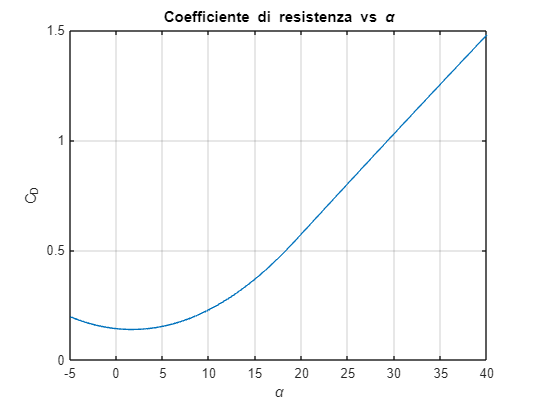

% è stato verificato che chiede tutto in gradi

v_alphaB_deg = linspace(-5,40,50);

v_CD = zeros(1,length(v_alphaB_deg));
for i_alpha = 1:length(v_alphaB_deg)
    v_CD(i_alpha) = CD(v_alphaB_deg(i_alpha));
end
figure(2)
plot(v_alphaB_deg, v_CD);
hold on
xlabel('\alpha');
ylabel('C_D');
grid on;
title('Coefficiente di resistenza vs \alpha')
hold off;

## Polare parabolica

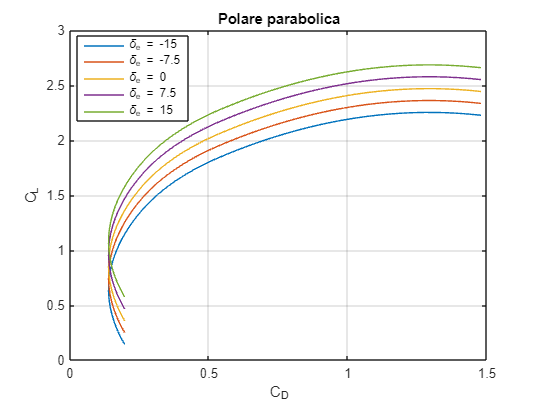

figure(3)
for i_delta_e = 1:length(v_delta_e_deg)
    plot(v_CD, m_CL(:,i_delta_e), 'DisplayName', ['\delta_e = ' num2str(v_delta_e_deg(i_delta_e))]);
    hold on

end
legend('show',"Position", [0.14768,0.70556,0.2,0.20476]);
xlabel('C_D');
ylabel('C_L');
grid on;
title('Polare parabolica')
hold off

% Il Cd non varia con la deflessione del'angolo di attacco, bensì
% all'aumentare della deflessione dell'angolo di attacco varia Cl come
% visto precedentemente

## Verifica della funzione CY_A

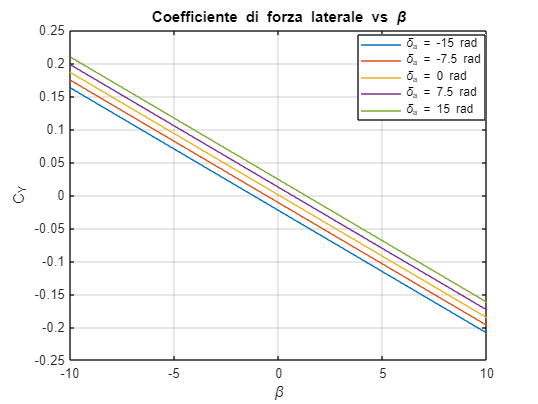

clear all;

% ora studiamo la funzione al variare di beta al variare di delta_a fissato delta_r nullo
% con angolo di attacco nullo
% st
v_beta_deg = linspace(-10,10,50);
v_delta_a_deg = linspace(-15,15,5);
alpha = 0;
delta_r = 0;
CY = zeros(length(v_beta_deg), length(v_delta_a_deg));

for i_beta = 1:length(v_beta_deg)
    beta = v_beta_deg(i_beta);
    for i_delta_a = 1:length(v_delta_a_deg)
        delta_a = v_delta_a_deg(i_delta_a);
        CY(i_beta, i_delta_a) = CY_A(alpha, beta, delta_a, delta_r);
    end
end
figure
for i_delta_a = 1:length(v_delta_a_deg)
    plot(v_beta_deg, CY(:,i_delta_a), 'DisplayName', ['\delta_a = ' num2str(v_delta_a_deg(i_delta_a)), ' rad']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\beta');
ylabel('C_Y');
grid on;
title('Coefficiente di forza laterale vs \beta')
hold off;

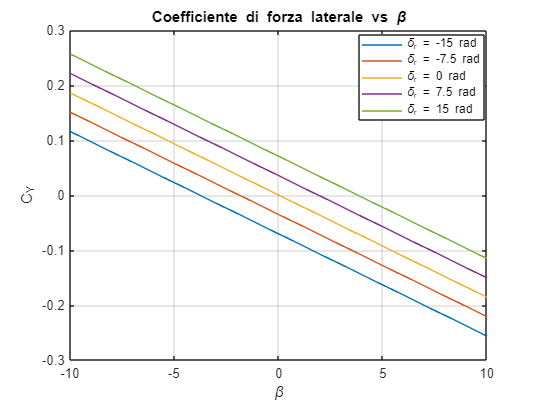

% Studiamo la funzione al variare di delta_r prendendo delta_a e alpha
% nullo,
v_delta_r_deg = linspace(-15,15,5);
alpha = 0;
delta_a = 0;
CY = zeros(length(v_beta_deg), length(v_delta_r_deg));

for i_beta = 1:length(v_beta_deg)
    beta = v_beta_deg(i_beta);
    for i_delta_r = 1:length(v_delta_r_deg)
        delta_r = v_delta_r_deg(i_delta_r);
        CY(i_beta, i_delta_r) = CY_A(alpha, beta, delta_a, delta_r);
    end
end
figure
for i_delta_r = 1:length(v_delta_r_deg)
    plot(v_beta_deg, CY(:,i_delta_r), 'DisplayName', ['\delta_r = ' num2str(v_delta_r_deg(i_delta_r)), ' rad']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\beta');
ylabel('C_Y');
grid on;
title('Coefficiente di forza laterale vs \beta')
hold off;

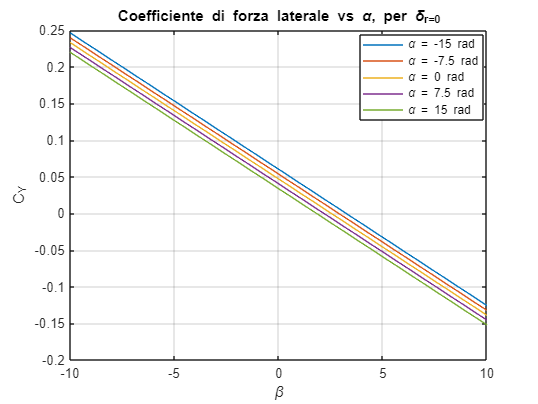

% sappiamo che le superfici di controllo diventano meno prestanti
% % all'aumentare dell'angolo di attacco, qui studiamo solo la dipendenza
% da alpha per delta_r=10 e delta_A nullo
v_alpha_deg = linspace(-15,15,5);
delta_r = 10;
delta_a = 0;
CY = zeros(length(v_beta_deg), length(v_alpha_deg));

for i_beta = 1:length(v_beta_deg)
    beta = v_beta_deg(i_beta);
    for i_alpha = 1:length(v_alpha_deg)
        alpha = v_alpha_deg(i_alpha);
        CY(i_beta, i_alpha) = CY_A(alpha, beta, delta_a, delta_r);
    end
end
figure
for i_alpha = 1:length(v_alpha_deg)
    plot(v_beta_deg, CY(:,i_alpha), 'DisplayName', ['\alpha = ' num2str(v_alpha_deg(i_alpha)), ' rad']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\beta');
ylabel('C_Y');
grid on;
title('Coefficiente di forza laterale vs \alpha, per \delta_r=0')
hold off;

## MOMENTI

## Verifica della funzione Cpitch

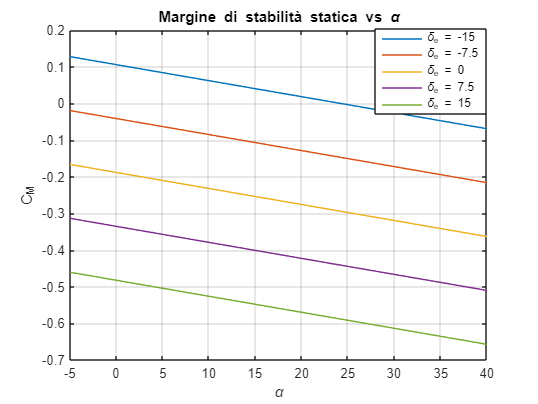


% Questa funzione riceve in entrata un vettore di tre variabili quali:
% alpha, delta_e, q.

% Viene chiamata nella funzione di costo e nelle eq del moto,
% è stato verificato che chiede delta_e in gradi e q in rad/s. Sebbene
% nella funzione di costo ciò non sia  veificato, si vede che è covertito
% inizialmente in radianti e mai più cambiato, lo stesso valore di C_M_q è
% più grande di C_M_alpha, sebbene alpha abbia più influenza sul C_M,
% quindi capiamo che  q viene trattato in radianti.


% Studieremo prima la funzione al variare di delta_e fissando q nullo

clear all;
v_alphaB_deg = linspace(-5,40,50);
q = 0;
v_delta_e_deg = linspace(-15,15,5);

m_CM = zeros(length(v_alphaB_deg), length(v_delta_e_deg));
for i_alpha = 1:length(v_alphaB_deg)
    alphaB = v_alphaB_deg(i_alpha);
    for i_delta_e = 1:length(v_delta_e_deg)
        delta_e = v_delta_e_deg(i_delta_e);
        m_CM(i_alpha, i_delta_e) = Cpitch(alphaB, delta_e, q);
    end
end
figure

for i_delta_e = 1:length(v_delta_e_deg)
    plot(v_alphaB_deg, m_CM(:,i_delta_e), 'DisplayName', ['\delta_e = ' num2str(v_delta_e_deg(i_delta_e))]);
    hold on

end
legend('show',"Position",[0.70125,0.72223,0.2,0.20476]);
xlabel('\alpha');
ylabel('C_M');
grid on;
title('Margine di stabilità statica vs \alpha')
hold off;

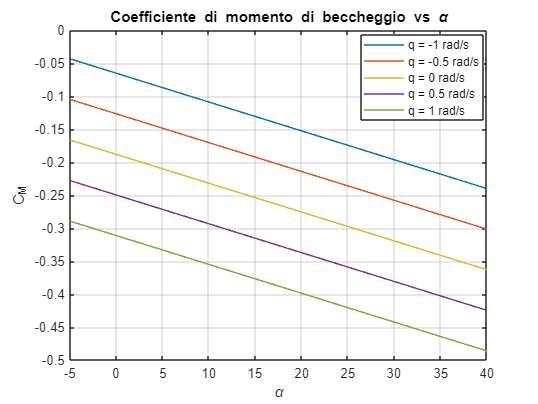

% Più l'elevatore è deflesso verso il basso minore è CM ovvero stai
% picchiando
clear all;
% ora studiamo la funzione al variare di q fissanto delta_e nullo
v_alphaB_deg = linspace(-5,40,50);
delta_e = 0;
v_q_deg_s = linspace(-1,1,5);

m_CM = zeros(length(v_alphaB_deg), length(v_q_deg_s));
for i_alpha = 1:length(v_alphaB_deg)
    alphaB = v_alphaB_deg(i_alpha);
    for i_q = 1:length(v_q_deg_s)
        q = v_q_deg_s(i_q);
        m_CM(i_alpha, i_q) = Cpitch(alphaB, delta_e, q);
    end
end
figure
for i_q = 1:length(v_q_deg_s)
    plot(v_alphaB_deg, m_CM(:,i_q), 'DisplayName', ['q = ' num2str(v_q_deg_s(i_q)), ' rad/s']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\alpha');
ylabel('C_M');
grid on;
title('Coefficiente di momento di beccheggio vs \alpha')
hold off;

## Verifica della funzione Croll

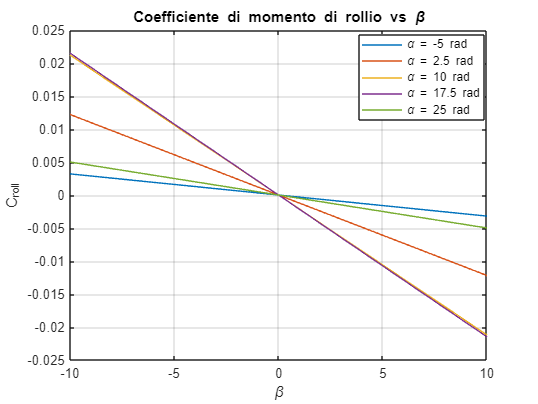


clear all;
v_beta_deg = linspace(-10,10,50);
v_alpha_deg = linspace(-5,25,5);
delta_a = 0;
delta_r = 0;
p = 0;
r = 0;

m_Croll = zeros(length(v_beta_deg), length(v_alpha_deg));

for i_beta = 1:length(v_beta_deg)
    beta = v_beta_deg(i_beta);
    for i_alpha = 1:length(v_alpha_deg)
        alpha = v_alpha_deg(i_alpha);
        m_Croll(i_beta, i_alpha) = Croll(alpha, beta, delta_a, delta_r,p,r);
    end
end
figure
for i_alpha = 1:length(v_alpha_deg)
    plot(v_beta_deg, m_Croll(:,i_alpha), 'DisplayName', ['\alpha = ' num2str(v_alpha_deg(i_alpha)), ' rad']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\beta');
ylabel('C_roll');
grid on;
title('Coefficiente di momento di rollio vs \beta')
hold off;

% con questo altro tipo di plot si vede invece come C_roll_beta vari al
% variare di alpha, in particolare l'effetto diedro, che è la pendenza di
% queste rette, è sempre negativo perché stabilizzante, e più è negativo
% più il velivolo sarà stabile, i valori massimi di C_roll_beta si hanno
% per  alpha = 17.5 e alpha = 10, ovvero ad alti angoli di attacco, ma
% vicini alla condizione di linearità, quando si va nella non  linearità
% poi l'effetto diminuisce. Una possibile spiegazione a ciò è che questo effetto sia dovuto alla
% freccia delle ali, l'ala sottovento vede la corrente arrivare più
% perpendicolare al leading edge grazie al beta, mentre quella sopravento
% vede una componente sempre minore, questo squilibrio è chiaramente aumentato
% da alpha tuttavia a 15gradi stacca il flusso e mentre l'ala spravento
% porta ancora quella su quella sottovento stacca il flusso e perde portanza
% e quindi l'effetto è minore


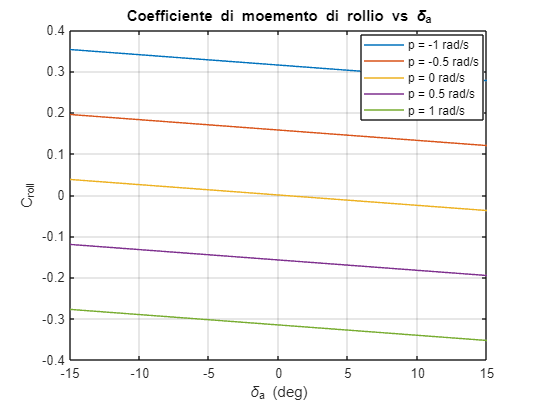

% Vediamo ora come varia il C_roll al variare della deflessione
% dell'alettone, studieremo la funzione al variare dell' alettone stesso,
% in modo tale che la derivata sarà proprio la potenza di comando Croll_delta_a
% e come altra variabile  metteremo p, che a differenza del resto è in rad al secondo.

clear all;
v_delta_a_deg = linspace(-15,15,50); % deg
v_p = linspace(-1,1,5); % rad/s
alpha = 0;
beta = 0;
delta_r = 0;
r = 0;

m_Croll = zeros(length(v_delta_a_deg), length(v_p));

for i_delta_a = 1:length(v_delta_a_deg)
    delta_a = v_delta_a_deg(i_delta_a);
    for i_p = 1:length(v_p)
        p = v_p(i_p);
        m_Croll(i_delta_a, i_p) = Croll(alpha, beta, delta_a, delta_r,p,r);
    end
end
figure
for i_p = 1:length(v_p)
    plot(v_delta_a_deg, m_Croll(:,i_p), 'DisplayName', ['p = ' num2str(v_p(i_p)), ' rad/s']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\delta_a (deg)');
ylabel('C_roll');
grid on;
title('Coefficiente di moemento di rollio vs \delta_a')
hold off;

% si vede che se do alettone negativo il Croll è positivo, quindi la
% convenzione è europea. Tuttavia mi sembra un po troppo poco potente
% l'effetto dell'alettone. Inoltre, si vede lalpha'effetto di smorzamento dovuto
% a p, infatti più p è grande più C_roll assume valori negativi, questo
% perché l'effetto è smorzante.

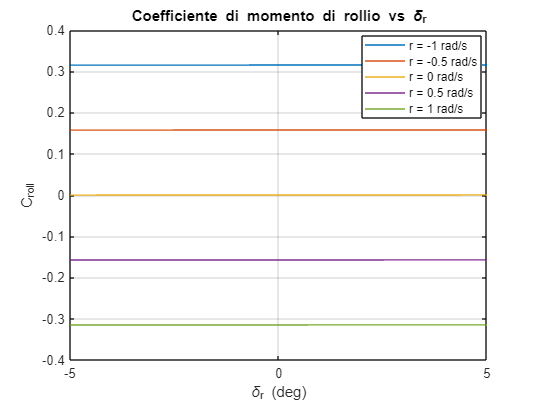

% Adesso studiamo gli effetti incrociati, vediamo come vengono influenzati
% il C_roll_delta_r e l'effetto di dipendenza da r

clear all;
v_delta_r_deg = linspace(-5,5,50); % deg
v_r = linspace(-1,1,5); % rad/s
alpha = 0;
beta = 0;
delta_a = 0;
r = 0;

m_Croll = zeros(length(v_delta_r_deg), length(v_r));

for i_delta_r = 1:length(v_delta_r_deg)
    delta_r = v_delta_r_deg(i_delta_r);
    for i_r = 1:length(v_r)
        p = v_r(i_r);
        m_Croll(i_delta_r, i_r) = Croll(alpha, beta, delta_a, delta_r,p,r);
    end
end
figure
for i_r = 1:length(v_r)
    plot(v_delta_r_deg, m_Croll(:,i_r), 'DisplayName', ['r = ' num2str(v_r(i_r)), ' rad/s']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\delta_r (deg)');
ylabel('C_roll');
grid on;
title('Coefficiente di momento di rollio vs \delta_r')
hold off;

% Si nota che per rudder positivo ho momento positivo, ovvero questo è
% l'effetto incrociato ed è instabilizzante, il rudder tende a far abbattere
% le ali nel verso in cui sta facendo imbardare, ovvero aumenta l'effetto di virata
% aggiungendo questo contributo al rollio. In più si vede come anche r
% dia un effetto instabilizzante in quanto una r positiva significa una
% imbardata a destra, che fa si che il timone veda un beta da sinistra, generando portanza
% e causando un momento di rollio che tende a far virare a sinistra, ciò significa che quindi darà
% momento di rollio neativo come infatti conferma il grafico.


## Verifica di Cyaw

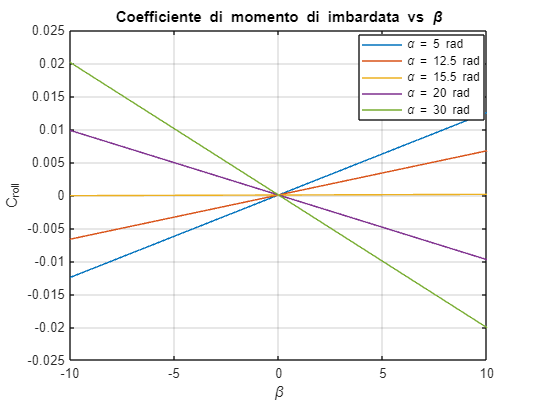

clear all;
v_beta_deg = linspace(-10,10,50);
v_alpha_deg = [5, 12.5, 15.5 , 20, 30];
delta_a = 0;
delta_r = 0;
r = 0;

m_Cyaw = zeros(length(v_beta_deg), length(v_alpha_deg));

for i_beta = 1:length(v_beta_deg)
    beta = v_beta_deg(i_beta);
    for i_alpha = 1:length(v_alpha_deg)
        alpha = v_alpha_deg(i_alpha);
        m_Cyaw(i_beta, i_alpha) = Cyaw(alpha, beta, delta_a, delta_r,r);
    end
end
figure
for i_alpha = 1:length(v_alpha_deg)
    plot(v_beta_deg, m_Cyaw(:,i_alpha), 'DisplayName', ['\alpha = ' num2str(v_alpha_deg(i_alpha)), ' rad']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\beta');
ylabel('C_roll');
grid on;
title('Coefficiente di momento di imbardata vs \beta')
hold off;

% se alpha è tra -5 e 10 non si ha dipendenza di alpha, si ha una
% dipendenza tra 10 e 25, mentre per valori superiori a 25, il coefficiente
% di imbardata torna a non dipendere da alpha
% La pendenza di queste rette, ovvero C_N_beta è detta stabilità
% direzionale


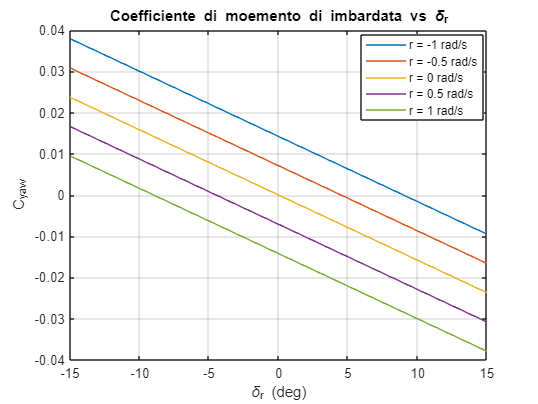

% Vediamo ora come varia il C_yaw al variare della deflessione
% del rudder, studieremo la funzione al variare del rudder stesso,
% in modo tale che la pendenza sarà proprio la potenza di comando
% C_yaw_delta_r
% e come altra variabile  metteremo p, che a differenza del resto è in rad al secondo.
clear all;
v_delta_r_deg = linspace(-15,15,50); % deg
v_r = linspace(-1,1,5); % rad/s
alpha = 0;
beta = 0;
delta_a = 0;

m_Cyaw = zeros(length(v_delta_r_deg), length(v_r));

for i_delta_r = 1:length(v_delta_r_deg)
    delta_r = v_delta_r_deg(i_delta_r);
    for i_r = 1:length(v_r)
        r = v_r(i_r);
        m_Cyaw(i_delta_r, i_r) = Cyaw(alpha, beta, delta_a, delta_r,r);
    end
end
figure
for i_r = 1:length(v_r)
    plot(v_delta_r_deg, m_Cyaw(:,i_r), 'DisplayName', ['r = ' num2str(v_r(i_r)), ' rad/s']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\delta_r (deg)');
ylabel('C_yaw');
grid on;
title('Coefficiente di moemento di imbardata vs \delta_r')
hold off;

% Si vede che per rudder  delta_r positivo (a sinistra) imbardi a sinistra ovvero
% momento di imbardata negativo, quindi la convenzione è europea.
% Si vede poi l'effetto di smorzamento dell'imbardata dovuto a r, infatti
% più aumenta r, ovvero più imbardo velocemente verso sinistra, più il
% coefficiente di Cyaw diminuisce, ovvero tende a imbardare a destra.
% Ciò accade perchè il timone vede un beta generato dalla rotazione e
% tende a stabilizzare il velivolo

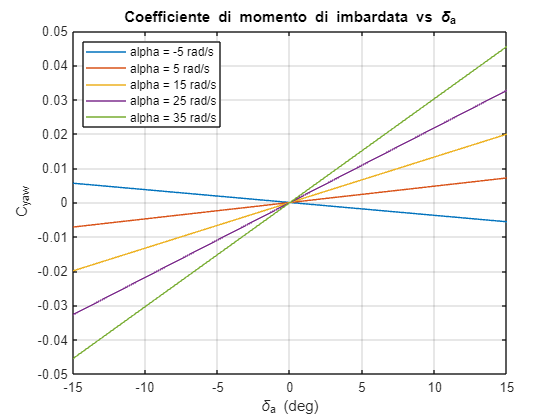

% Adesso studiamo gli effetti incrociati, vediamo come viene influenzato
% il C_yaw_delta_a

clear all;
v_delta_a_deg = linspace(-15,15,50); % deg
v_alpha = linspace(-5,35,5); % rad/s
beta = 0;
delta_r = 0;
r = 0;

m_Cyaw = zeros(length(v_delta_a_deg), length(v_alpha));

for i_delta_a = 1:length(v_delta_a_deg)
    delta_a = v_delta_a_deg(i_delta_a);
    for i_alpha = 1:length(v_alpha)
        alpha = v_alpha(i_alpha);
        m_Cyaw(i_delta_a, i_alpha) = Cyaw(alpha, beta, delta_a, delta_r,r);
    end
end
figure
for i_alpha = 1:length(v_alpha)
    plot(v_delta_a_deg, m_Cyaw(:,i_alpha), 'DisplayName', ['alpha = ' num2str(v_alpha(i_alpha)), ' rad/s']);
    hold on

end
legend('show',"Position", [0.67536,0.70794,0.21964,0.20476]);
xlabel('\delta_a (deg)');
ylabel('C_yaw');
grid on;
title('Coefficiente di momento di imbardata vs \delta_a')
hold off;

legend("Position", [0.14392,0.69398,0.25651,0.21287])

% si vede che qui c'è l'effetto incorciato che è instabilizzante,
% ovvero più è deflesso l'alettone positivamente l'alettone, ovvero virata
% a sinistra, più aumenta il C_yaw



